# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Paula Fernández Sánchez, Luis Ramos Triguero, María Díez Martínez**

**Fecha:17/11/2026**

# Tema 4. Ejercicio 1.1. Identificación de círculos

1) Lee la imagen

RGB = imread('pillsetc.png');
imshow(RGB);

2) Umbraliza la imagen

I = rgb2gray(RGB);
bw = imbinarize(I);
imshow(bw)

3) Elimina el ruido

Usando operaciones morfológicas se eliminan los píxeles que no pertenecen a los objetos de interés.

% remove all object containing fewer than 30 pixels
bw = bwareaopen(bw,30);

% fill a gap in the pen's cap
se = strel('disk',2);
bw = imclose(bw,se);

% fill any holes, so that regionprops can be used to estimate
% the area enclosed by each of the boundaries
bw = imfill(bw,'holes');

imshow(bw)

4) Encuentra los contornos

Nos centramos sólo en los límites exteriores. La opción `'noholes' `acelerará el proceso al evitar que la función `bwboundaries` busque contornos internos. 

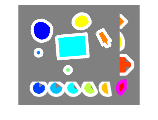

[B,L,n] = bwboundaries(bw,'noholes'); % Obtiene los contornos exteriores de los objetos y la matriz de etiquetas.

% Display the label matrix 
imshow(label2rgb(L, @jet, [.5 .5 .5]))

hold on  % to draw the next in the same figure

% draws the boundaries of each object.
for k = 1:n
  boundary = B{k};
  plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end

Se pide:

- Utilice la ayuda de Matlab para conseguir información sobre la función `regionprops `(parámetros requeridos, propiedades que calcula, etc.).

- Usando dicha función, calcule el área y el perímetro de cada objeto de la imagen previa. 

- A partir del área y el perímetro de cada objeto devueltos por `regionprops`, calcule su circularidad mediante la expresión F=4*pi*A/(p^2) estudiada en teoría. 

- Umbralice el valor de la circularidad y resalte los objetos que sean aproximadamente circulares (p.ej., pintando las boundaries de color diferente). 

- Utilice un slider para comprobar cómo influye el valor del umbral en los objetos seleccionados. 

stats = regionprops(L,'Area','Perimeter');
A = [stats.Area];
p = [stats.Perimeter];

F = 4*pi*A./(p.^2)

F =     1.0036    1.0610    0.7845    1.0569    1.0081    0.6606


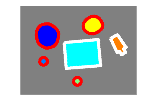


umbral = 0.85;
figure
imshow(label2rgb(L, @jet, [.5 .5 .5]))
hold on
for k = 1:n
  boundary = B{k};
  if F(k) > umbral
    plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2)
  else
    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
  end
end

# Tema 4. Ejercicio 1.2. Identificación de objetos cóncavos/convexos

- Cargue la imagen `'Figure1.jpg'` 

- Utilice la función `regionprops` para calcular el área, el área convexa y el índice de convexidad (Solidity). Visualice una tabla con las tres propiedades para todos los objetos de la imagen.

- Resalte la envolvente convexa ('ConvexHull') de cada objeto: en blanco para los objetos cóncavos y en magenta para los convexos, utilizando el valor de `Solidity` para diferenciarlos.

- Utilice un slider para umbralizar el índice de convexidad dentro del rango de valores obtenido (según aparecen en la tabla del punto 2) y compruebe qué objetos son seleccionados al variar el valor del umbral. Justifique si la selección es correcta según los valores obtenidos.

JUSTIFICACION: Al mover el slider se ve que los objetos convexos (el círculo, el triángulo y las dos porciones de círculo) tienen un Solidity casi 1. Los cóncavos (los comecocos grandes y pequeños, las cruces y la flecha) dan valores más bajos, porque su envolvente convexa abarca huecos que no son del objeto. Con un umbral de 0.95 la selección es correcta. Si lo bajo mucho, algunos cóncavos salen como convexos, y si lo acerco a 1, salen todos como cóncavos.

RGB = imread('Figure1.jpg');
I = rgb2gray(RGB);
bw = imbinarize(I);
bw = ~bw;
[B,L,n] = bwboundaries(bw,'noholes');

T = regionprops('table',L,'Area','ConvexArea','Solidity')

T = 14×3 table
    Area     ConvexArea    Solidity
    _____    __________    ________

     8965       9045       0.99116 
     7176       7246       0.99034 
     3752       4289        0.8748 
    12243      13940       0.87826 
     3485       4154       0.83895 
     3031       3664       0.82724 
     8031       8121       0.98892 
     7820       8920       0.87668 
     2862       3428       0.83489 
    10655      12887        0.8268 
     2428       2666       0.91073 
     2432       3184       0.76382 
     5500       7740       0.71059 
     1794       1829       0.98086 


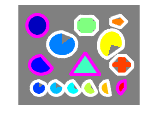


stats = regionprops(L,'ConvexHull','Solidity');
umbral = 0.95;
figure
imshow(label2rgb(L, @jet, [.5 .5 .5]))
hold on
for k = 1:n
  h = stats(k).ConvexHull;
  if stats(k).Solidity < umbral
    plot(h(:,1), h(:,2), 'w', 'LineWidth', 2)
  else
    plot(h(:,1), h(:,2), 'm', 'LineWidth', 2)
  end
end